*Copyright NhungLe-GFZ Potsdam, Germany*

*Create: 11/10/2024*

clear all
warning('off')


# Read input file


data = readtable("D:\Test_App\FLX_AU-ASM_FLUXNET2015_SUBSET_DD_2010-2014_2-4.xlsx", ...
    "Sheet","FLX_AU-ASM_FLUXNET2015_SUBSET_D","Range","A:BS");


# Prepare input data

%% convert TIMESTAMP into datatime
data_Date = datetime(string(data.TIMESTAMP),'inputFormat','yyyyMMdd');
DOY = day(data_Date,'dayofyear');

%% Remove -9999 into NaN for processing Time series
for i=1:numel(data(1,:))

    a = table2array (data(:,i));
    index = find(a(:) ==-9999);
    if isempty(index)==0
        a(index)="NaN";
        data(:,i) = array2table(a);
    end

end

 %% Convert Calendar Date into Modified Julian Date (MJD)
YY=str2double(extractBetween(string(data.TIMESTAMP),1,4));
MM=str2double(extractBetween(string(data.TIMESTAMP),5,6));
DD=str2double(extractBetween(string(data.TIMESTAMP),7,8));
Julian_Date=((1461 * (YY + 4800 + (MM - 14)/12))/4 + ...
    (367 * (MM - 2 - 12 * ((MM - 14)/12)))/12 - ...
    (3 * ((YY + 4900 + (MM - 14)/12)/100))/4 + DD - 32075)-2400000.5;
clear YY MM DD

# Clean outliers

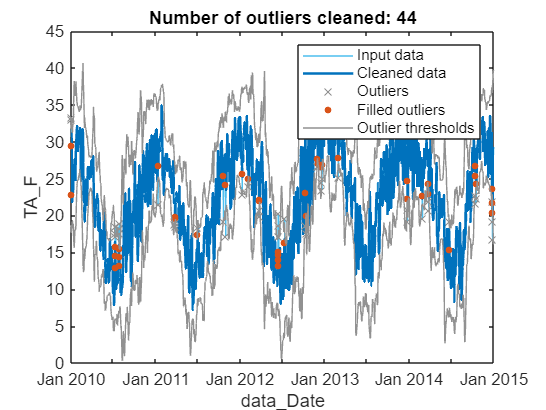

% Fill outliers
[Clean_data,outlierIndices,thresholdLow,thresholdHigh] = filloutliers(data, ...
    "pchip","movmedian",days(30),"ThresholdFactor",2.5, ...
    "SamplePoints",data_Date);

% Display results
figure
plot(data_Date,data.TA_F,"SeriesIndex",6,"DisplayName","Input data")
hold on
plot(data_Date,Clean_data.TA_F,"SeriesIndex",1,"LineWidth",1.5, ...
    "DisplayName","Cleaned data")

% Plot outliers
plot(data_Date(outlierIndices(:,2)),data.TA_F(outlierIndices(:,2)),"x", ...
    "Color",[145 145 145]/255,"DisplayName","Outliers")

% Plot filled outliers
plot(data_Date(outlierIndices(:,2)),Clean_data.TA_F(outlierIndices(:,2)),".", ...
    "MarkerSize",12,"SeriesIndex",2,"DisplayName","Filled outliers")

% Plot outlier thresholds
plot([data_Date(:); missing; data_Date(:)], ...
    [thresholdHigh.TA_F(:); missing; thresholdLow.TA_F(:)], ...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

hold off
title("Number of outliers cleaned: " + nnz(outlierIndices(:,2)))
legend
ylabel("TA_F","Interpreter","none")
xlabel("data_Date","Interpreter","none")

clear thresholdLow thresholdHigh


%% save clearn data

writetable(Clean_data,"D:\Test_App\FLX_AU-ASM_FLUXNET2015_SUBSET_DD_2010-2014_2-4.xlsx", ...
    "Sheet","SUBSET_D_Clean")

# Fit sine function

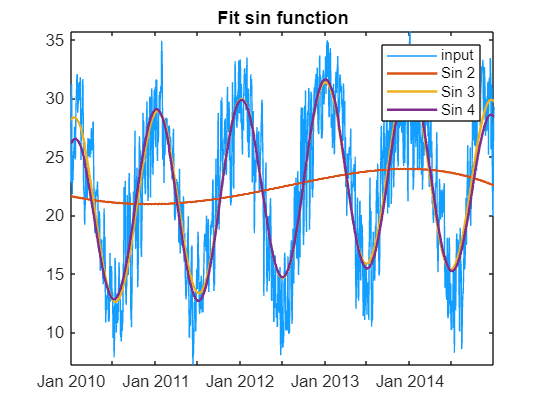

xinput=Julian_Date;
yinput=Clean_data.TA_F;

%% select the number of degree for function approximation
kmax=4;

[coeff_names,coeffs,RMSE_Sin,Residual,Fit_model] = fitfunction(xinput, yinput,kmax);

Clean_data.Fit_model_1 = Fit_model(:,1);
Clean_data.Fit_model_2 = Fit_model(:,2);
Clean_data.Fit_model_3 = Fit_model(:,3);
Clean_data.Fit_model_4 = Fit_model(:,4);
Clean_data.Residual_1 = Residual(:,1);
Clean_data.Residual_2 = Residual(:,2);
Clean_data.Residual_3 = Residual(:,3);
Clean_data.Residual_4 = Residual(:,4);

figure;
plot(data_Date,Clean_data.TA_F,"Color",[0.07,0.62,1.00])
hold on
plot(data_Date,Fit_model(:,(2:4)),"LineWidth",1.5)
legend("input","Sin 2","Sin 3","Sin 4")
title("Fit sin function")
axis tight
hold off

# Functions

function [coeff_names,coeffs,RMSE_Sin,Residual,Fit_model] = fitfunction(xinput, yinput,kmax)

[xData, yData] = prepareCurveData(xinput, yinput);

for k=1:kmax

typefig="sin"+ k;
ft = fittype( typefig );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';

% Fit model to data.
[fitresult, gof, output] = fit(xData, yData, ft, opts );

 fitresult;
 gof;
 outputRes=output.residuals; % residuals = detrended obs

% Find values of fit function
coeff_names=transpose(coeffnames(fitresult));
coeff_names(k)=coeff_names(k);
coeffs = coeffvalues(fitresult);
coeffs(k)=coeffs(k);

% Extract the fit_model
 outputY=feval(fitresult,xData);
 Fit_model(:,k)=outputY;

% Compute Residuals and Errors
Residual(:,k)=outputRes;

% RMSE
RMSE_Sine=gof.rmse;
RMSE_Sin(k)=RMSE_Sine;

end
end

